clc; clear; clear all;

load('ct_image');
png_img_info = uint8(png_img_info(:,:,:));

options.FrangiScaleRange=[1.5 3];
options.BlackWhite=false;
options.FrangiScaleRatio = 0.3;
filtered=FrangiFilter3D(png_img_info, options);

Current Frangi Filter Sigma: 1.5
Current Frangi Filter Sigma: 1.8
Current Frangi Filter Sigma: 2.1
Current Frangi Filter Sigma: 2.4
Current Frangi Filter Sigma: 2.7
Current Frangi Filter Sigma: 3


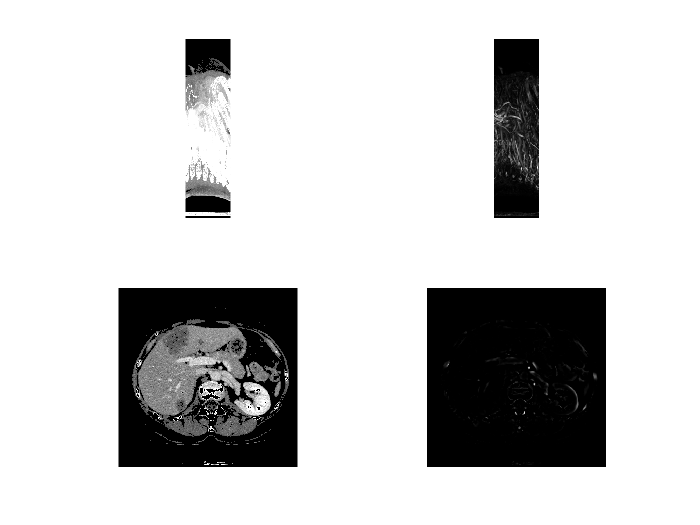

figure,
subplot(2,2,1), imshow(squeeze(max(png_img_info,[],2)),[])
subplot(2,2,2), imshow(squeeze(max(filtered,[],2)),[])
subplot(2,2,3), imshow(png_img_info(:,:,75),[])
subplot(2,2,4), imshow(filtered(:,:,75),[])

save_path = 'D:\文件\学习\毕业论文_CT图像中的血管分割\代码\Hessian\frangi_filter_version2a\filtered\';
filtered_new = zeros(size(filtered));
filtered_new(filtered ~= 0) = 255;

for i = 0:size(filtered,3)-1
    % 构造文件名
    if i < 10
        num_str = '00';
        filename = ['image_', num_str, num2str(i), '.png'];
    elseif i<100
        num_str = '0' ;
        filename = ['image_', num_str, num2str(i), '.png'];
    else
        filename = ['image_', num2str(i), '.png'];
    end
    % 将当前二维矩阵写入到PNG文件中
    imwrite(uint8(filtered_new(:,:,i+1)), fullfile(save_path, filename));
end